motor1 = -1.*dataVector(: , 1)+180;         % Angle of all of motor 1
motor2 = -1.*dataVector(: , 2)+180;         % Angle of all of motor 2
sensordata = dataVector(: , 3);     % Sensor data
r = sensordata .* sin(deg2rad(motor2)); % Spherical
% x = r.*cos(deg2rad(motor1));
% y = r.*sin(deg2rad(motor1));
distance=-.152.*sensordata+84.8

distance =    84.6510
   84.6526
   84.6510
   84.6510
   84.6510
   84.6526
   84.6510
   84.6526
   84.6510
   84.6586


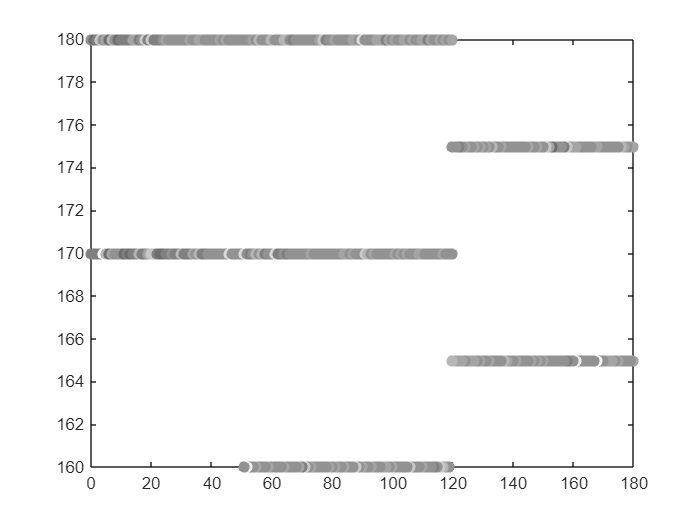

[x,y,z] = sph2cart(deg2rad(motor1), deg2rad(motor2), distance);
x=rescale(x);
n=rescale(sensordata);
for i= 1:762
    plot(motor1(i),motor2(i), "color", [1-n(i) 1-n(i) 1-n(i)], "Marker",".", MarkerSize=20)
    hold on
end
hold off
%
for i = 1:941                    % Checks sensor data to see if there is something there1037
     if sensordata(i) > 200
                % display rows that fulfill all conditions.        
        plot(motor1(i), motor2(i),'-o','Color',"b") 
 hold on
                                      % if there is plot it
    else
     end
  end
 hold off



% for i = 1:527          % Checks sensor data to see if there is something there
%    if r(i) > 200*sin(deg2rad(motor2(i))) % 200 
%        %disp(r(i,:))        % display rows that fulfill all conditions.
%        plot(x(i), y(i),'-o','Color',"b") 
%        hold on
%                                     % if there is plot it
%    else
    %end
%end



% 
% for i = 1:1098                     % Checks sensor data to see if there is something there1037
%     if sensordata(i) > 450 
%        %disp(sensordata(i,:))        % display rows that fulfill all conditions.        
%        scatter(z(i),x(i)) 
% hold on
%                                      % if there is plot it
%     else
%     end
%  end
% hold off
figure